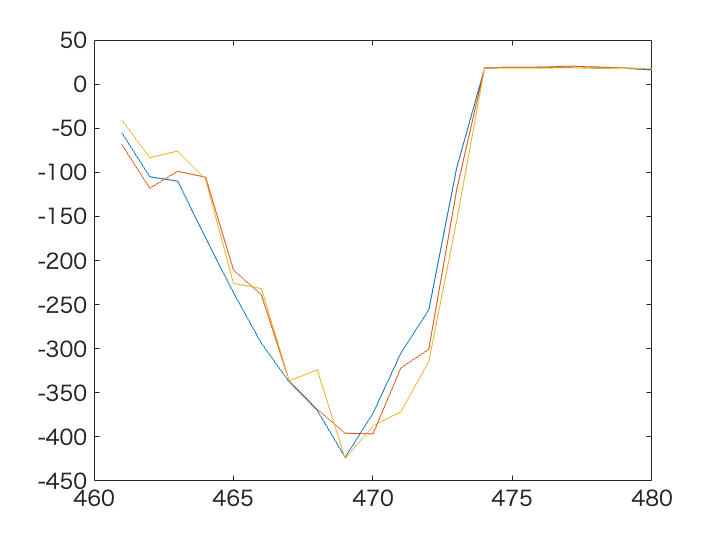

load('/Users/shinjirotakeda/Library/CloudStorage/GoogleDrive-takeda-shinjiro234@g.ecc.u-tokyo.ac.jp/マイドライブ/probedata/processed/240111028.mat','data2D','grid2D');
[~,xPointList] = get_axis_x_multi(grid2D,data2D);

Et_t1 = zeros(1,20);
t = 461:480;
m = 1;
for i = 61:80
    idxR = knnsearch(grid2D.rq(:,1),xPointList.r(i));
    idxZ = knnsearch(grid2D.zq(1,:).',xPointList.z(i));
    Et_t1(m) = mean(data2D.Et(max(1,idxR-3):min(idxR+3,numel(grid2D.rq(:,1))),max(1,idxZ-3):min(numel(grid2D.zq(1,:)),idxZ+3),i),'all');
    m = m+1;
end

load('/Users/shinjirotakeda/Library/CloudStorage/GoogleDrive-takeda-shinjiro234@g.ecc.u-tokyo.ac.jp/マイドライブ/probedata/processed/240111029.mat','data2D','grid2D');
[~,xPointList] = get_axis_x_multi(grid2D,data2D);

Et_t2 = zeros(1,20);
t = 461:480;
m = 1;
for i = 61:80
    idxR = knnsearch(grid2D.rq(:,1),xPointList.r(i));
    idxZ = knnsearch(grid2D.zq(1,:).',xPointList.z(i));
    Et_t2(m) = mean(data2D.Et(max(1,idxR-3):min(idxR+3,numel(grid2D.rq(:,1))),max(1,idxZ-3):min(numel(grid2D.zq(1,:)),idxZ+3),i),'all');
    m = m+1;
end

load('/Users/shinjirotakeda/Library/CloudStorage/GoogleDrive-takeda-shinjiro234@g.ecc.u-tokyo.ac.jp/マイドライブ/probedata/processed/240111030.mat','data2D','grid2D');
[~,xPointList] = get_axis_x_multi(grid2D,data2D);

Et_t3 = zeros(1,20);
t = 461:480;
m = 1;
for i = 61:80
    idxR = knnsearch(grid2D.rq(:,1),xPointList.r(i));
    idxZ = knnsearch(grid2D.zq(1,:).',xPointList.z(i));
    Et_t3(m) = mean(data2D.Et(max(1,idxR-3):min(idxR+3,numel(grid2D.rq(:,1))),max(1,idxZ-3):min(numel(grid2D.zq(1,:)),idxZ+3),i),'all');
    m = m+1;
end

figure;plot(t,Et_t1);hold on;plot(t,Et_t2);plot(t,Et_t3);

Et_t = [Et_t1;Et_t2;Et_t3]

Et_t =   -55.3655 -105.0835 -110.0447 -174.3206 -236.6472 -293.8272 -337.7508 -369.8690 -423.0999 -373.2158 -305.0084 -255.9078  -94.9830   17.9782   18.2687   19.3848   18.8509   17.9230   17.9745   16.0519
  -68.5338 -118.1144  -98.7814 -105.5899 -210.8777 -238.9269 -336.8460 -368.6238 -395.8021 -396.5762 -321.7184 -300.5793 -119.5177   18.6831   19.1624   19.1777   20.3266   19.4468   18.4521   17.1840
  -41.0902  -83.3958  -75.9307 -107.9574 -226.0242 -231.8377 -336.4153 -323.7981 -424.4083 -387.6720 -371.4046 -314.5526 -154.8544   18.1754   18.3757   18.1965   18.6608   18.2327   18.0181   17.4051


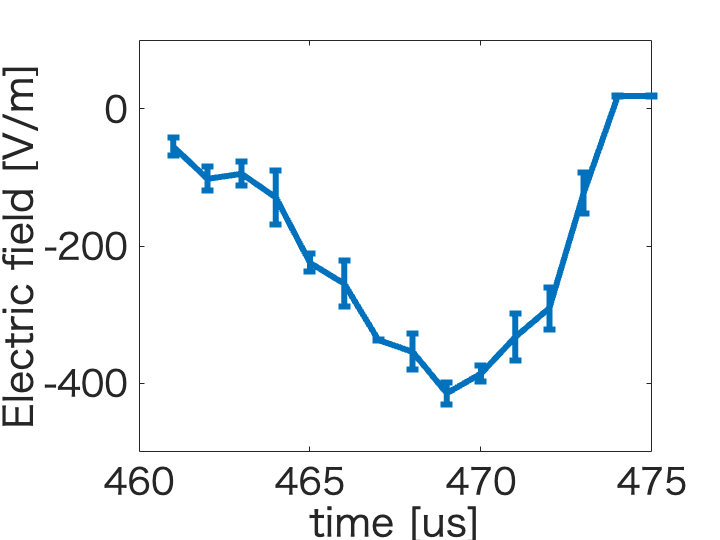

EtM = mean(Et_t,'omitmissing');
EtD = std(Et_t,'omitmissing');
figure;errorbar(t,EtM,EtD,'LineWidth',3);
xlabel('time [us]');ylabel('Electric field [V/m]');
ax = gca; ax.FontSize = 18;
xlim([460 475]);yticks([-400 -200 0]);xticks([460 465 470 475]);